clear all
close all
clc
TUTU=[4 5 6];
for i=1:length(TUTU)
    TU=TUTU(i)
    if TU==4
        load neutral_curve_linear_TU_4.mat
        plot(realwavenumber,realRa.^2,'k--',LineWidth=1.5)
        hold on

        load neutral_curve_nonlinear_TU_4.mat

        plot(kk,R,'k-',LineWidth=1.5)
    end
    if TU==5
        load neutral_curve_linear_TU_5.mat
        plot(realwavenumber,realRa.^2,'k--',LineWidth=1.5)
        hold on

        load neutral_curve_nonlinear_TU_5.mat

        plot(kk,R,'k-',LineWidth=1.5)
    end
    if TU==6
        load neutral_curve_linear_TU_6.mat
        plot(realwavenumber,realRa.^2,'k--',LineWidth=1.5)
        hold on

        load neutral_curve_nonlinear_TU_6.mat

        plot(kk,R,'k-',LineWidth=1.5)
        annotation('textbox',...
    [0.795642857142856 0.649047619047622 0.0932857142857138 0.0914285714285725],...
    'String','$T_U=6$',...
    'Rotation',30,...
    'LineStyle','none',...
    'Interpreter','latex',...
    'FontSize',14,...
    'FitBoxToText','off');
        annotation('textbox',...
    [0.781357142857142 0.412857142857144 0.100428571428572 0.0895238095238103],...
    'String','$T_U=5$',...
    'Rotation',25,...
    'LineStyle','none',...
    'Interpreter','latex',...
    'FontSize',14,...
    'FitBoxToText','off');
        annotation('textbox',...
    [0.777071428571429 0.23 0.117571428571429 0.112380952380953],...
    'String',{'$T_U=4$'},...
    'Rotation',17,...
    'LineStyle','none',...
    'Interpreter','latex',...
    'FontSize',14,...
    'FitBoxToText','off');
    end
end

TU = 4

TU = 5

TU = 6

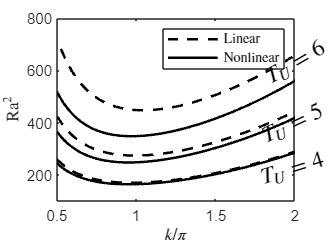

legend('Linear','Nonlinear',Interpreter='latex')
xlabel('$k/\pi$',Interpreter='latex')
ylabel('$\mathrm{Ra}^2$',Interpreter='latex')
axis([0.5 2 100 800])